% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/Final_Trial/";

file_name = "Polystyrene_2024-06-20_65_100_2024-06-20-15.24.29.553.csv";
file_path = strcat(data_path,file_name);
poly_june20 = readmatrix(file_path);

file_name = "Polystyrene_2024-06-21_65_100_2024-06-21-11.25.16.000.csv";
file_path = strcat(data_path,file_name);
poly_june21 = readmatrix(file_path);

file_name = "Polystyrene_2024-06-23_65_100_2024-06-23-18.54.05.243.csv";
file_path = data_path+file_name;
poly_june23 = readmatrix(file_path);

file_name = "Silicon_2024-06-20_50_100_2024-06-20-15.18.50.393.csv";
file_path = strcat(data_path,file_name);
silicon_june20 = readmatrix(file_path);

file_name = "Silicon_2024-06-21_50_100_2024-06-21-11.19.46.800.csv";
file_path = strcat(data_path,file_name);
silicon_june21 = readmatrix(file_path);

file_name = "Silicon_2024-06-23_50_100_2024-06-23-18.50.02.417.csv";
file_path = strcat(data_path,file_name);
silicon_june23 = readmatrix(file_path);

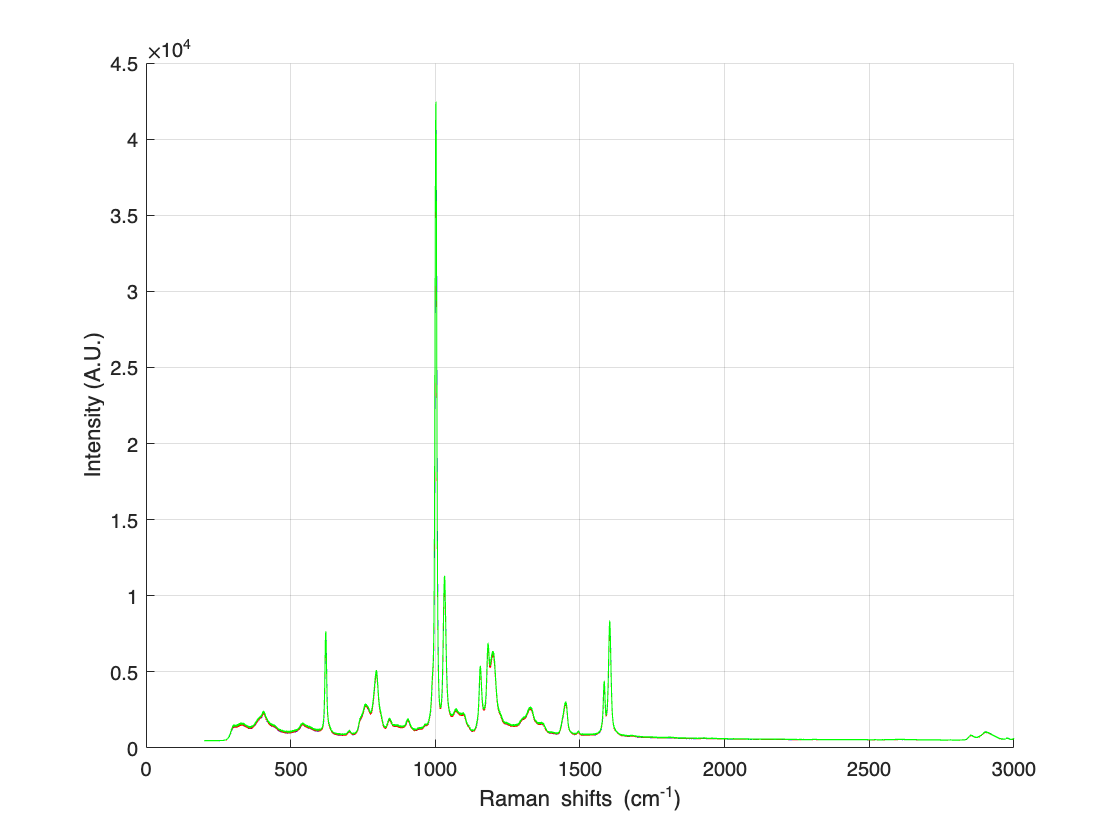

% Configuring and plotting unprocessed data

wavenumber = silicon_june20(1,:);
sil1 = silicon_june23;
sil2 = silicon_june20;
sil3 = silicon_june21;
poly1 = poly_june23;
poly2 = poly_june20;
poly3 = poly_june21;

% trimming standard sample data to these WN's
t1 = 200;
t2 = 3000;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
sil1(:, sil1(1, :) <= t1) = [];
sil1(:, sil1(1, :) >= t2) = [];
sil2(:, sil2(1, :) <= t1) = [];
sil2(:, sil2(1, :) >= t2) = [];
sil3(:, sil3(1, :) <= t1) = [];
sil3(:, sil3(1, :) >= t2) = [];
poly1(:, poly1(1, :) <= t1) = [];
poly1(:, poly1(1, :) >= t2) = [];
poly2(:, poly2(1, :) <= t1) = [];
poly2(:, poly2(1, :) >= t2) = [];
poly3(:, poly3(1, :) <= t1) = [];
poly3(:, poly3(1, :) >= t2) = [];

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, poly1(2:end,:), '-b');
plot(wavenumber, poly2(2:end,:), '-r');
plot(wavenumber, poly3(2:end,:), '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

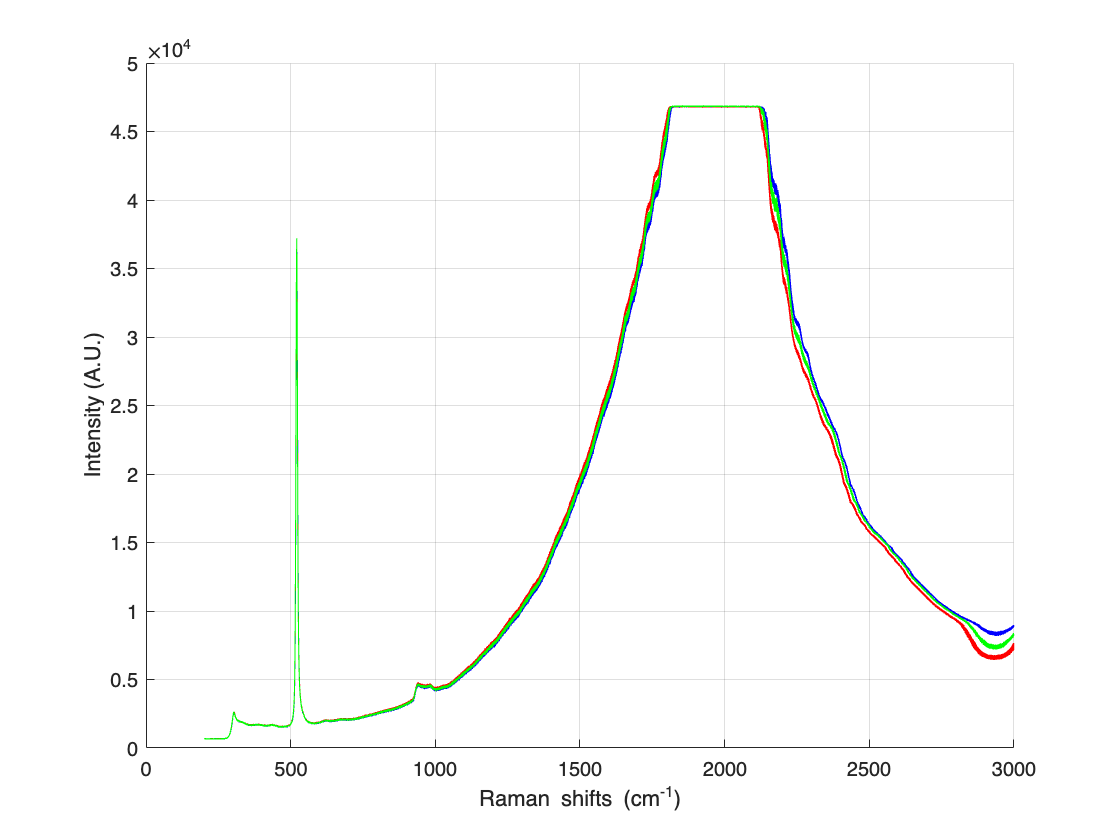


figure;
hold on;
grid on;
plot(wavenumber, sil1(2:end,:), '-b');
plot(wavenumber, sil2(2:end,:), '-r');
plot(wavenumber, sil3(2:end,:), '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

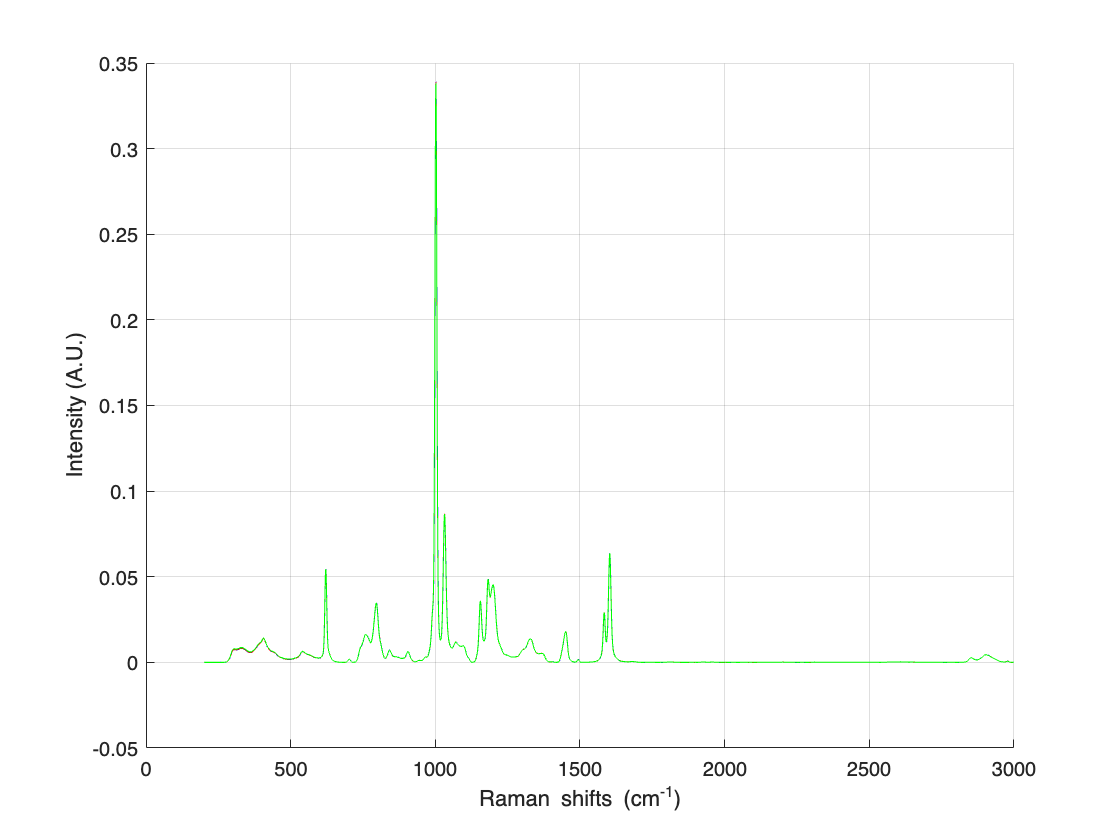

% Preprocessing the data

pro_sil1 = apply(sil1, [6,1,8,2,5,6,7]);
pro_sil2 = apply(sil2, [6,1,8,2,5,6,7]);
pro_sil3 = apply(sil3, [6,1,8,2,5,6,7]);

pro_poly1 = apply(poly1, [6,1,8,2,5,6,7]);
pro_poly2 = apply(poly2, [6,1,8,2,5,6,7]);
pro_poly3 = apply(poly3, [6,1,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_poly1, '-b');
plot(wavenumber, pro_poly2, '-r');
plot(wavenumber, pro_poly3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

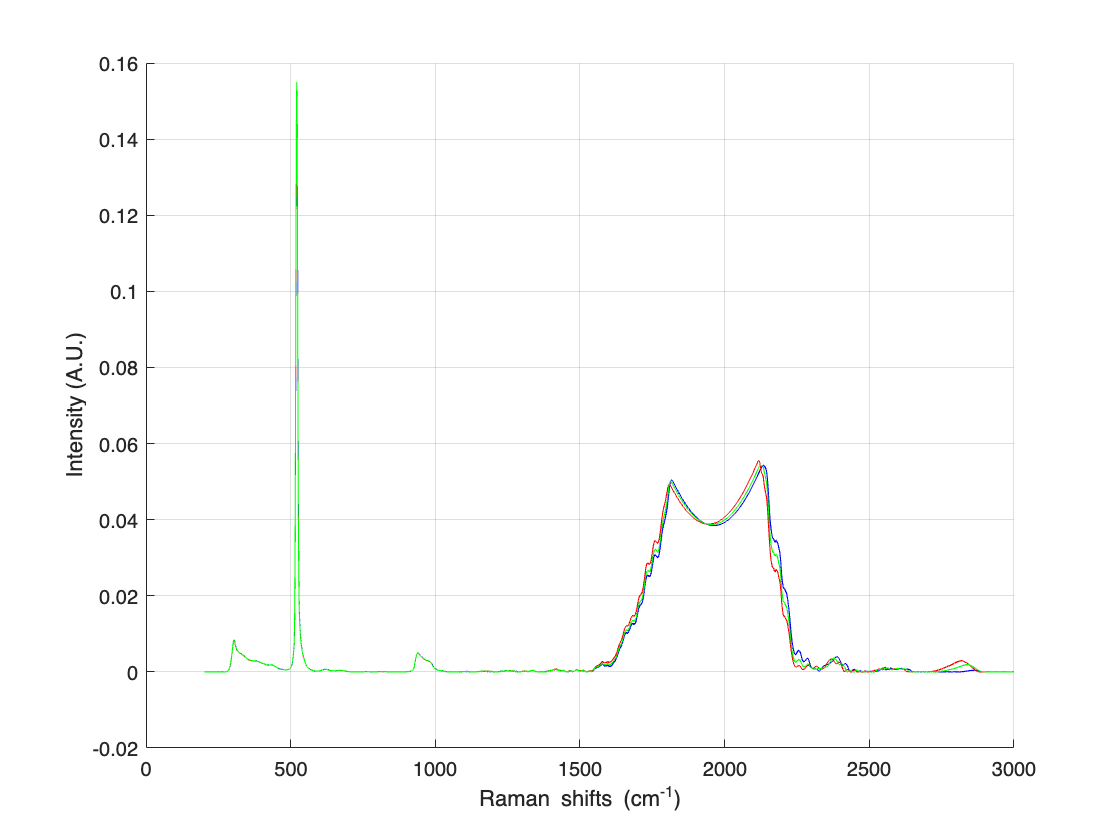


figure;
hold on;
grid on;
plot(wavenumber, pro_sil1, '-b');
plot(wavenumber, pro_sil2, '-r');
plot(wavenumber, pro_sil3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

% Data for 321 cm^-1 peak
Trial1 = pro_sil1(:, 321);
Trial2 = pro_sil2(:, 321);
Trial3 = pro_sil3(:, 321);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);

% Number of spectra in each trial
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);

% Display results
fprintf('t and p values for pairwise comparisons at 321 cm^-1 peak:\n');

t and p values for pairwise comparisons at 321 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = 41.9998, p = 0.0000, df = 9.8238


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = -0.1342, p = 0.8962, df = 9.0361


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = -35.3725, p = 0.0000, df = 9.6098


% % ANOVA test for Polystyrene
% 
% % Reformat the intensity data into a single column
% intensities_poly = [pro_poly1(:); pro_poly2(:); pro_poly3(:)];
% 
% % Create a wavenumber label for each intensity reading
% wavenumbers = repmat(wavenumber(:), 6 * 3, 1);  % wavenumber repeated for each intensity reading
% 
% % Create a grouping variable for day
% days = [repmat({'May 15'}, numel(pro_poly1), 1); 
%         repmat({'May 16'}, numel(pro_poly2), 1); 
%         repmat({'May 17'}, numel(pro_poly3), 1)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_poly, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});
% disp('Polystyrene ANOVA Table:');
% disp(tbl);

% % ANOVA test for Silicon
% 
% % Reformat the intensity data into a single column
% intensities_sil = [pro_sil1(:); pro_sil2(:); pro_sil3(:)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_sil, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});
% disp('Silicon ANOVA Table:');
% disp(tbl);

% figure; % Create a new figure for the box plot
% boxplot(intensities_poly, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Polystyrene');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 15', 'May 16', 'May 17'});
% 
% figure; % Create a new figure for the box plot
% boxplot(intensities_sil, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Silicon');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 15', 'May 16', 'May 17'});

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end